# Planteamiento de la cinemática inversa de la posición para un robot Dofbot

## Resumen

Se presenta el planteamiento de la cinemática inversa de la posición del robot serial Dofbot de cinco grados de libertad. El modelo cinemático inverso de la posición planteado es mediente una solución geometrica del robot. 

## Definición de las funcines 

Matriz de transformaciones homógeneas

%Deficición de la función de manera simbolica
syms Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j)

%Definición de la transformación homógenea general
Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j) = [cos(ai_j)*cos(bi_j) cos(ai_j)*sin(bi_j)*sin(gi_j)-sin(ai_j)*cos(gi_j) sin(ai_j)*sin(gi_j)+cos(ai_j)*sin(bi_j)*cos(gi_j) x_i_j; sin(ai_j)*cos(bi_j) cos(ai_j)*cos(gi_j)+sin(ai_j)*sin(bi_j)*sin(gi_j) sin(ai_j)*sin(bi_j)*cos(gi_j)-cos(ai_j)*sin(gi_j) y_i_j; -sin(bi_j) cos(bi_j)*sin(gi_j) cos(bi_j)*cos(gi_j) z_i_j; 0 0 0 1]

$$Tij(x\_i\_j, y\_i\_j, z\_i\_j, gi\_j, bi\_j, ai\_j) = \left(\begin{array}{cccc} \cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{bi}}_{j}\right) & \cos\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right)-\cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right) & \sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right)+\cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right) & x_{i,j}\\ \cos\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right) & \cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right)+\sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & \cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)-\cos\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & y_{i,j}\\ -\sin\left({\mathrm{bi}}_{j}\right) & \cos\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & \cos\left({\mathrm{bi}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right) & z_{i,j}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## Plateamiento del modelo de la cinemática directa del robot

Para el planteamiento del modelo del robot se establece la relaciones de posición y orientación de cada eslabón al asociarlos con un sistema de referencia relativo relacionado, el cual se presenta en la siguiente figura. 

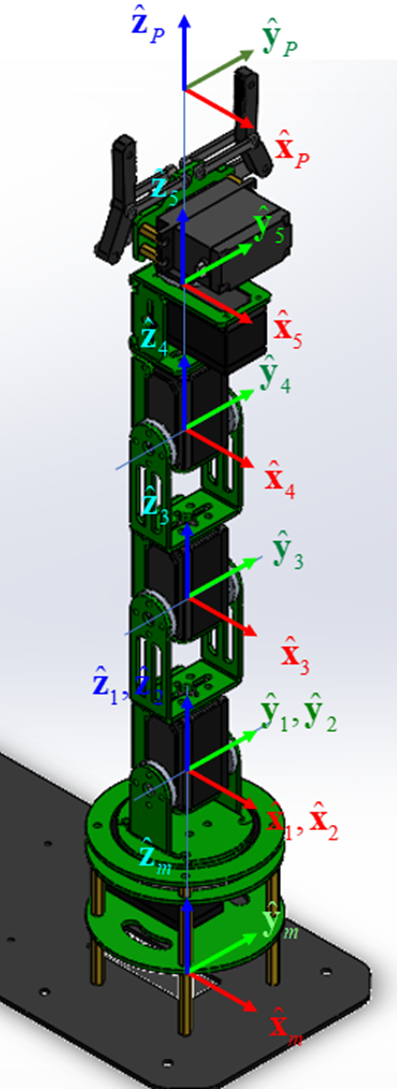

En sistma de referencia {m} está asociacdo al sistema inercial del robot y el sistema {P} está asociado con el efector final del robot en específico el punto en el cual los dedos de este pude tomar un objeto sin problemas. 

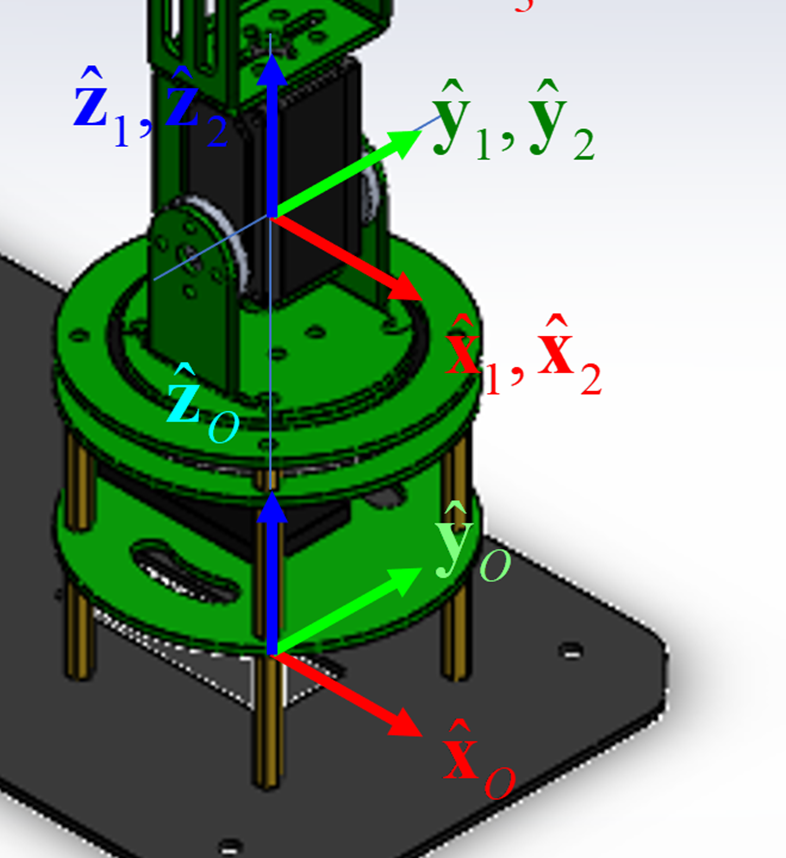

En la figura anterios se presenta los sistemas de referenia {1} y {2} cuyo origen comparten el mismo punto, el sistema {1} está asociado con el movimiento de la cintura del robot cuya junta rotacional gira con respecto al eje ${\widehat{\mathbf{z}} }_1$ y el sistema de referecia {2} está asociado con el sistema del hombro del robot el cual gira con respecto al eje ${\widehat{y} }_2$. La matriz de tranformación homógenea que describe la relaciones de posición y de orientación entre el sistema {1} y el sistema {0} es:

syms T_0_1 z_0_1 theta_0_1 T_1_2 theta_1_2 x_dot_0_1 x_ddot_0_1 

T_0_1

$$T\_0\_1 = T_{0,1}$$

T_0_1 = Tij(0,0,z_0_1,0,0,theta_0_1)

$$T\_0\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{0,1}\right) & -\sin\left(\theta_{0,1}\right) & 0 & 0\\ \sin\left(\theta_{0,1}\right) & \cos\left(\theta_{0,1}\right) & 0 & 0\\ 0 & 0 & 1 & z_{0,1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


x_dot_0_1

$$x\_dot\_0\_1 = {\dot{x}}_{0,1}$$


x_ddot_0_1

$$x\_ddot\_0\_1 = {\ddot{x}}_{0,1}$$

El sistema {2} está asociado a la artículación del hombro del robot y su movimiento es una rotación con respecto al eje ${\widehat{y} }_2$, la matriz de transformación de este sistema es:

T_1_2

$$T\_1\_2 = T_{1,2}$$

T_1_2 = Tij(0,0,0,0,theta_1_2,0)

$$T\_1\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{1,2}\right) & 0 & \sin\left(\theta_{1,2}\right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{1,2}\right) & 0 & \cos\left(\theta_{1,2}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

En la siguiente imagen se presenta el sistema de referencia {3} asociado al codo del robot y el sistema de referencia {4} asociado al recodo de la muñeca del robot (bend).

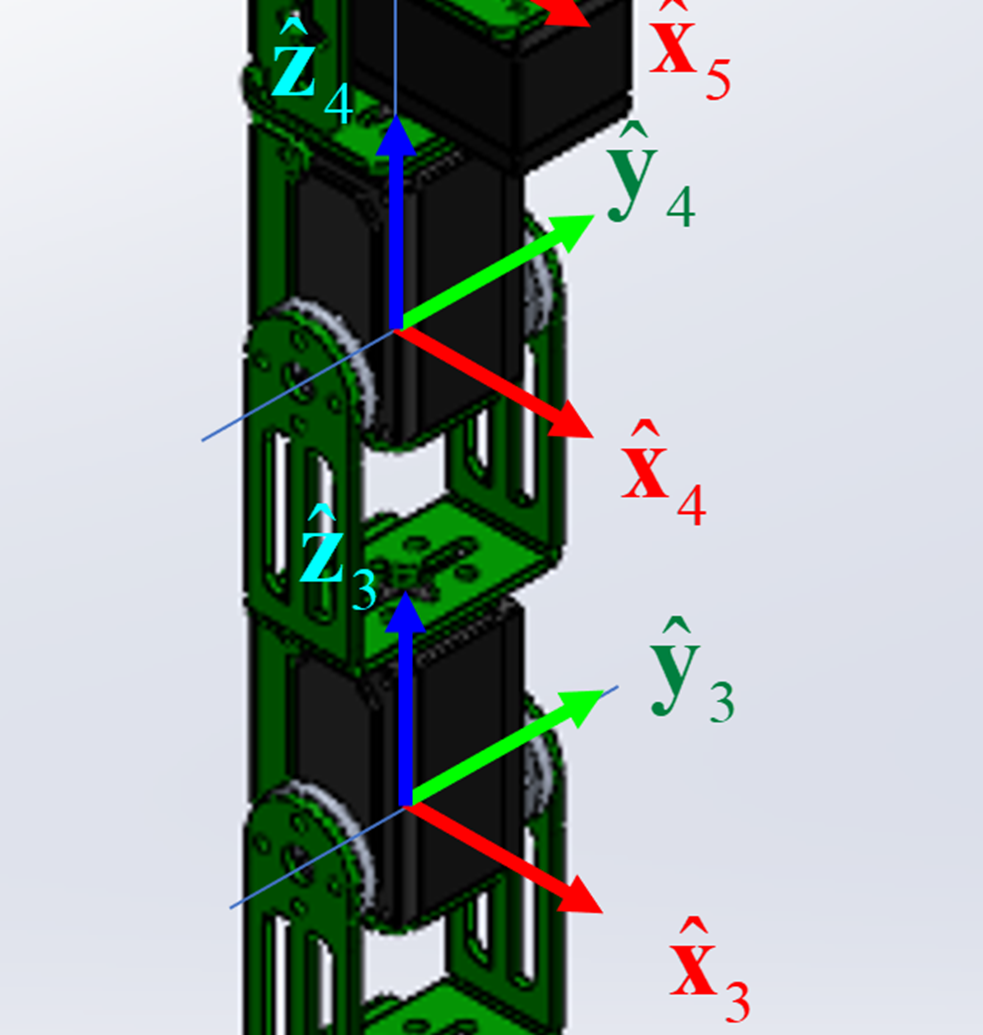

Las relaciones de posición y orientación entre el hombro y el codo del robot está dada en la matriz ${}^2{\mathbf{T}}_3$la cual describe la longitud del antebrazo del robot ${}^2z_3$ y la restricción de la junta rotación asociada con el giro sobre el eje ${\widehat{y} }_3$.

syms T_2_3 z_2_3 theta_2_3 T_3_4 z_3_4 theta_3_4
T_2_3

$$T\_2\_3 = T_{2,3}$$

T_2_3 = Tij(0,0,z_2_3,0,theta_2_3,0)

$$T\_2\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{2,3}\right) & 0 & \sin\left(\theta_{2,3}\right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{2,3}\right) & 0 & \cos\left(\theta_{2,3}\right) & z_{2,3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Las relaciones de posición y orientación entre el codo y el recodo del robot está dada en la matriz ${}^3{\mathbf{T}}_4$la cual describe la longitud del antebrazo del robot ${}^3z_4$ y la restricción de la junta rotación asociada con el giro sobre el eje ${\widehat{y} }_4$.

T_3_4

$$T\_3\_4 = T_{3,4}$$

T_3_4 = Tij(0,0,z_3_4,0,theta_3_4,0)

$$T\_3\_4 = \left(\begin{array}{cccc} \cos\left(\theta_{3,4}\right) & 0 & \sin\left(\theta_{3,4}\right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{3,4}\right) & 0 & \cos\left(\theta_{3,4}\right) & z_{3,4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

La muñeca del robot (wrist) está asocida la sistema {5} y punto donde el gripper puede tomar un objeto está asociado sobre el sistema {P}.

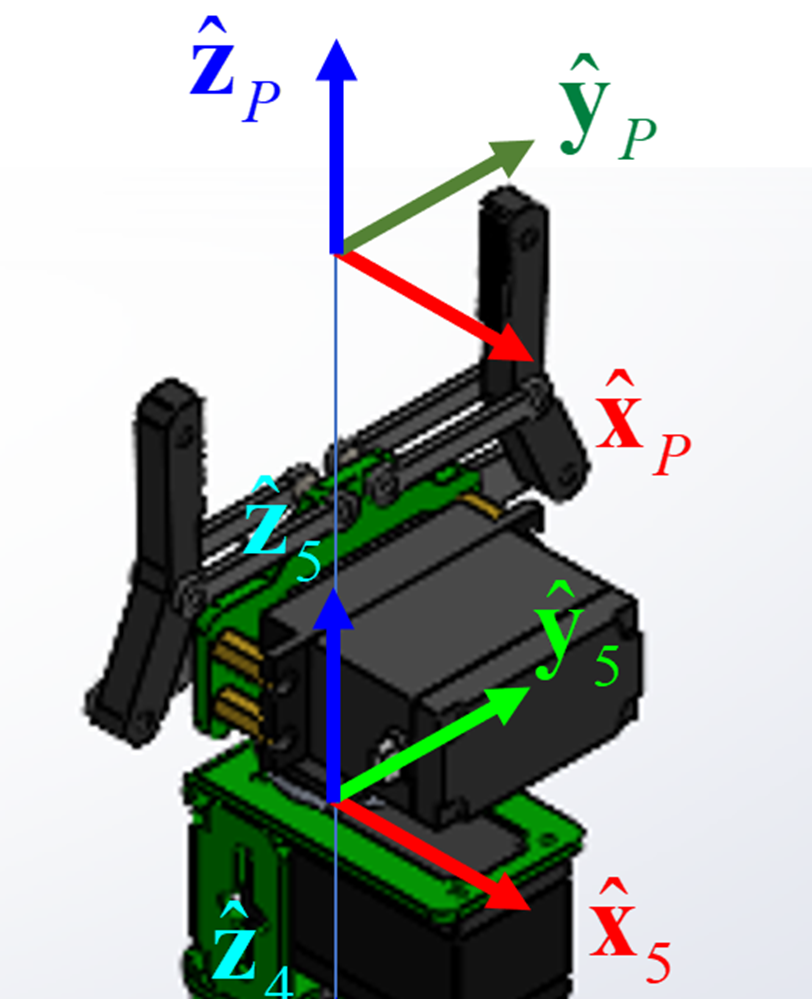

Las relaciones de posición y orientación entre el recodo y la muñeca del robot está dada en la matriz ${}^4{\mathbf{T}}_5$la cual describe la longitud del antebrazo del robot ${}^4z_5$ y la restricción de la junta rotación asociada con el giro sobre el eje ${\widehat{z} }_5$.

syms T_4_5 z_4_5 theta_4_5 T_5_P z_5_P

T_4_5

$$T\_4\_5 = T_{4,5}$$

T_4_5 = Tij(0,0,z_4_5,0,0,theta_4_5)

$$T\_4\_5 = \left(\begin{array}{cccc} \cos\left(\theta_{4,5}\right) & -\sin\left(\theta_{4,5}\right) & 0 & 0\\ \sin\left(\theta_{4,5}\right) & \cos\left(\theta_{4,5}\right) & 0 & 0\\ 0 & 0 & 1 & z_{4,5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Y la matriz de la relación entre la muñeca y el gripper del robot es:

T_5_P

$$T\_5\_P = T_{5,P}$$

T_5_P = Tij(0,0,z_5_P,0,0,0)

$$T\_5\_P = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & z_{5,P}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

El modelo cinemático directo de la posición es:

syms T_0_P

T_0_P = simplify(T_0_1*T_1_2*T_2_3*T_3_4*T_4_5*T_5_P)

$$T\_0\_P = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1}\,\cos\left(\theta_{0,1}\right)\,\cos\left(\theta_{4,5}\right)-\sin\left(\theta_{0,1}\right)\,\sin\left(\theta_{4,5}\right) & -\cos\left(\theta_{4,5}\right)\,\sin\left(\theta_{0,1}\right)-\sigma_{1}\,\cos\left(\theta_{0,1}\right)\,\sin\left(\theta_{4,5}\right) & \sigma_{3}\,\cos\left(\theta_{0,1}\right) & \cos\left(\theta_{0,1}\right)\,\sigma_{2}\\ \cos\left(\theta_{0,1}\right)\,\sin\left(\theta_{4,5}\right)+\sigma_{1}\,\cos\left(\theta_{4,5}\right)\,\sin\left(\theta_{0,1}\right) & \cos\left(\theta_{0,1}\right)\,\cos\left(\theta_{4,5}\right)-\sigma_{1}\,\sin\left(\theta_{0,1}\right)\,\sin\left(\theta_{4,5}\right) & \sigma_{3}\,\sin\left(\theta_{0,1}\right) & \sin\left(\theta_{0,1}\right)\,\sigma_{2}\\ -\sigma_{3}\,\cos\left(\theta_{4,5}\right) & \sigma_{3}\,\sin\left(\theta_{4,5}\right) & \sigma_{1} & z_{0,1}+z_{3,4}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\cos\left(\theta_{1,2}\right)+z_{4,5}\,\sigma_{1}+z_{5,P}\,\sigma_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right)\\ \sigma_{2}=z_{4,5}\,\sigma_{3}+z_{5,P}\,\sigma_{3}+z_{3,4}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\sin\left(\theta_{1,2}\right)\\ \sigma_{3}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right) \end{array}$$

xi_O_P = [T_0_P(1,4);T_0_P(2,4);T_0_P(3,4);T_0_P(1,1);T_0_P(2,2);T_0_P(3,3)]

$$xi\_O\_P = \begin{array}{l} \left(\begin{array}{c} \cos\left(\theta_{0,1}\right)\,\sigma_{1}\\ \sin\left(\theta_{0,1}\right)\,\sigma_{1}\\ z_{0,1}+z_{3,4}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\cos\left(\theta_{1,2}\right)+z_{4,5}\,\sigma_{2}+z_{5,P}\,\sigma_{2}\\ \sigma_{2}\,\cos\left(\theta_{0,1}\right)\,\cos\left(\theta_{4,5}\right)-\sin\left(\theta_{0,1}\right)\,\sin\left(\theta_{4,5}\right)\\ \cos\left(\theta_{0,1}\right)\,\cos\left(\theta_{4,5}\right)-\sigma_{2}\,\sin\left(\theta_{0,1}\right)\,\sin\left(\theta_{4,5}\right)\\ \sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=z_{4,5}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right)+z_{5,P}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right)+z_{3,4}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\sin\left(\theta_{1,2}\right)\\ \sigma_{2}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right) \end{array}$$

J_theta = jacobian(xi_O_P,[theta_0_1,theta_1_2,theta_2_3,theta_3_4,theta_4_5])

$$J\_theta = \begin{array}{l} \left(\begin{array}{ccccc} -\sin\left(\theta_{0,1}\right)\,\sigma_{2} & \cos\left(\theta_{0,1}\right)\,\sigma_{1} & \cos\left(\theta_{0,1}\right)\,\sigma_{5} & \cos\left(\theta_{0,1}\right)\,\sigma_{8} & 0\\ \cos\left(\theta_{0,1}\right)\,\sigma_{2} & \sin\left(\theta_{0,1}\right)\,\sigma_{1} & \sin\left(\theta_{0,1}\right)\,\sigma_{5} & \sin\left(\theta_{0,1}\right)\,\sigma_{8} & 0\\ 0 & -z_{4,5}\,\sigma_{10}-z_{5,P}\,\sigma_{10}-\sigma_{9}-z_{2,3}\,\sin\left(\theta_{1,2}\right) & -z_{4,5}\,\sigma_{10}-z_{5,P}\,\sigma_{10}-\sigma_{9} & -z_{4,5}\,\sigma_{10}-z_{5,P}\,\sigma_{10} & 0\\ \sigma_{7} & \sigma_{3} & \sigma_{3} & \sigma_{3} & \sigma_{6}\\ \sigma_{6} & \sigma_{4} & \sigma_{4} & \sigma_{4} & \sigma_{7}\\ 0 & -\sigma_{10} & -\sigma_{10} & -\sigma_{10} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sigma_{11}+z_{2,3}\,\cos\left(\theta_{1,2}\right)+z_{4,5}\,\sigma_{12}+z_{5,P}\,\sigma_{12}\\ \sigma_{2}=z_{4,5}\,\sigma_{10}+z_{5,P}\,\sigma_{10}+\sigma_{9}+z_{2,3}\,\sin\left(\theta_{1,2}\right)\\ \sigma_{3}=-\sigma_{10}\,\cos\left(\theta_{0,1}\right)\,\cos\left(\theta_{4,5}\right)\\ \sigma_{4}=\sigma_{10}\,\sin\left(\theta_{0,1}\right)\,\sin\left(\theta_{4,5}\right)\\ \sigma_{5}=\sigma_{11}+z_{4,5}\,\sigma_{12}+z_{5,P}\,\sigma_{12}\\ \sigma_{6}=-\cos\left(\theta_{4,5}\right)\,\sin\left(\theta_{0,1}\right)-\sigma_{12}\,\cos\left(\theta_{0,1}\right)\,\sin\left(\theta_{4,5}\right)\\ \sigma_{7}=-\cos\left(\theta_{0,1}\right)\,\sin\left(\theta_{4,5}\right)-\sigma_{12}\,\cos\left(\theta_{4,5}\right)\,\sin\left(\theta_{0,1}\right)\\ \sigma_{8}=z_{4,5}\,\sigma_{12}+z_{5,P}\,\sigma_{12}\\ \sigma_{9}=z_{3,4}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)\\ \sigma_{10}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right)\\ \sigma_{11}=z_{3,4}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)\\ \sigma_{12}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right) \end{array}$$

Para el planteamiento de la solución del robot  se plantea el desacoplamiento de los elemetos de orientación del robot, por le que se establece la matriz de los elementos de posicionamiento del robot.

syms T_0_4 T_4_P

T_0_4

$$T\_0\_4 = T_{0,4}$$

T_0_4 = simplify(T_0_1*T_1_2*T_2_3*T_3_4)

$$T\_0\_4 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{3}\,\cos\left(\theta_{0,1}\right) & -\sin\left(\theta_{0,1}\right) & \sigma_{2}\,\cos\left(\theta_{0,1}\right) & \cos\left(\theta_{0,1}\right)\,\sigma_{1}\\ \sigma_{3}\,\sin\left(\theta_{0,1}\right) & \cos\left(\theta_{0,1}\right) & \sigma_{2}\,\sin\left(\theta_{0,1}\right) & \sin\left(\theta_{0,1}\right)\,\sigma_{1}\\ -\sigma_{2} & 0 & \sigma_{3} & z_{0,1}+z_{3,4}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\cos\left(\theta_{1,2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=z_{3,4}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\sin\left(\theta_{1,2}\right)\\ \sigma_{2}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right)\\ \sigma_{3}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right) \end{array}$$

Los elementos de orientación del robot están contenidos en la siguiente matriz

T_4_P = simplify(T_4_5*T_5_P)

$$T\_4\_P = \left(\begin{array}{cccc} \cos\left(\theta_{4,5}\right) & -\sin\left(\theta_{4,5}\right) & 0 & 0\\ \sin\left(\theta_{4,5}\right) & \cos\left(\theta_{4,5}\right) & 0 & 0\\ 0 & 0 & 1 & z_{4,5}+z_{5,P}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Para establecer el desacoplamiento es necesario establecer las matrices de transformación del robot.

Definición de las matrices de rotación

syms R_0_1 R_1_2 R_2_3 R_3_4 R_4_5 R_5_P R_0_4

R_0_1 = [T_0_1(1,1),T_0_1(1,2),T_0_1(1,3);T_0_1(2,1),T_0_1(2,2),T_0_1(2,3);T_0_1(3,1),T_0_1(3,2),T_0_1(3,3)]

$$R\_0\_1 = \left(\begin{array}{ccc} \cos\left(\theta_{0,1}\right) & -\sin\left(\theta_{0,1}\right) & 0\\ \sin\left(\theta_{0,1}\right) & \cos\left(\theta_{0,1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_1_2 = [T_1_2(1,1),T_1_2(1,2),T_1_2(1,3);T_1_2(2,1),T_1_2(2,2),T_1_2(2,3);T_1_2(3,1),T_1_2(3,2),T_1_2(3,3)]

$$R\_1\_2 = \left(\begin{array}{ccc} \cos\left(\theta_{1,2}\right) & 0 & \sin\left(\theta_{1,2}\right)\\ 0 & 1 & 0\\ -\sin\left(\theta_{1,2}\right) & 0 & \cos\left(\theta_{1,2}\right) \end{array}\right)$$

R_2_3 = [T_2_3(1,1),T_2_3(1,2),T_2_3(1,3);T_2_3(2,1),T_2_3(2,2),T_2_3(2,3);T_2_3(3,1),T_2_3(3,2),T_2_3(3,3)]

$$R\_2\_3 = \left(\begin{array}{ccc} \cos\left(\theta_{2,3}\right) & 0 & \sin\left(\theta_{2,3}\right)\\ 0 & 1 & 0\\ -\sin\left(\theta_{2,3}\right) & 0 & \cos\left(\theta_{2,3}\right) \end{array}\right)$$

R_3_4 = [T_3_4(1,1),T_3_4(1,2),T_3_4(1,3);T_3_4(2,1),T_3_4(2,2),T_3_4(2,3);T_3_4(3,1),T_3_4(3,2),T_3_4(3,3)]

$$R\_3\_4 = \left(\begin{array}{ccc} \cos\left(\theta_{3,4}\right) & 0 & \sin\left(\theta_{3,4}\right)\\ 0 & 1 & 0\\ -\sin\left(\theta_{3,4}\right) & 0 & \cos\left(\theta_{3,4}\right) \end{array}\right)$$

R_4_5 = [T_4_5(1,1),T_4_5(1,2),T_4_5(1,3);T_4_5(2,1),T_4_5(2,2),T_4_5(2,3);T_4_5(3,1),T_4_5(3,2),T_4_5(3,3)]

$$R\_4\_5 = \left(\begin{array}{ccc} \cos\left(\theta_{4,5}\right) & -\sin\left(\theta_{4,5}\right) & 0\\ \sin\left(\theta_{4,5}\right) & \cos\left(\theta_{4,5}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_5_P = [T_5_P(1,1),T_5_P(1,2),T_5_P(1,3);T_5_P(2,1),T_5_P(2,2),T_5_P(2,3);T_5_P(3,1),T_5_P(3,2),T_5_P(3,3)]

$$R\_5\_P = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

Matrices de rotación del desacoplamiento


R_0_4 = simplify(R_0_1*R_1_2*R_3_4)

$$R\_0\_4 = \left(\begin{array}{ccc} \cos\left(\theta_{1,2}+\theta_{3,4}\right)\,\cos\left(\theta_{0,1}\right) & -\sin\left(\theta_{0,1}\right) & \sin\left(\theta_{1,2}+\theta_{3,4}\right)\,\cos\left(\theta_{0,1}\right)\\ \cos\left(\theta_{1,2}+\theta_{3,4}\right)\,\sin\left(\theta_{0,1}\right) & \cos\left(\theta_{0,1}\right) & \sin\left(\theta_{1,2}+\theta_{3,4}\right)\,\sin\left(\theta_{0,1}\right)\\ -\sin\left(\theta_{1,2}+\theta_{3,4}\right) & 0 & \cos\left(\theta_{1,2}+\theta_{3,4}\right) \end{array}\right)$$


R_4_P = simplify(R_4_5*R_5_P)

$$R\_4\_P = \left(\begin{array}{ccc} \cos\left(\theta_{4,5}\right) & -\sin\left(\theta_{4,5}\right) & 0\\ \sin\left(\theta_{4,5}\right) & \cos\left(\theta_{4,5}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

### Planteamiento del desacoplamiento de la orientación del efector final

La orientación del efector final del robot estada por la matriz de rotación ${}^0{\mathbf{R}}_P$ la cual se calcula de la siguiente manera:


$${}^0{\mathbf{R}}_P={}^0{\mathbf{R}}_4{}^4{\mathbf{R}}_P={\mathbf{R}}_T$$


Donde la matriz ${}^0{\mathbf{R}}_4$está relacionada con los tres primeros grados de libertad del robot, y la matriz ${}^4{\mathbf{R}}_P$ esta relacionada directamente con la matriz de orientación del recodo y del codo del robot, y la matriz ${\mathbf{R}}_T$ describe al efector final del robot variables del espacio de trabajo. De la ecuación anterior se puede plantear la ubicación del sistema {4}


$${}^4{\mathbf{R}}_P={}^0{\mathbf{R}}^{-1}_4{\mathbf{R}}_T$$


Desarrollando 

syms R_4_P_esp x_0_P y_0_P z_0_P beta_0_P alpha_0_P T_T

T_T = Tij(x_0_P,y_0_P,z_0_P,0,beta_0_P,alpha_0_P)

$$T\_T = \left(\begin{array}{cccc} \cos\left(\alpha_{0,P}\right)\,\cos\left(\beta_{0,P}\right) & -\sin\left(\alpha_{0,P}\right) & \cos\left(\alpha_{0,P}\right)\,\sin\left(\beta_{0,P}\right) & x_{0,P}\\ \cos\left(\beta_{0,P}\right)\,\sin\left(\alpha_{0,P}\right) & \cos\left(\alpha_{0,P}\right) & \sin\left(\alpha_{0,P}\right)\,\sin\left(\beta_{0,P}\right) & y_{0,P}\\ -\sin\left(\beta_{0,P}\right) & 0 & \cos\left(\beta_{0,P}\right) & z_{0,P}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

R_T = [T_T(1,1),T_T(1,2),T_T(1,3);T_T(2,1),T_T(2,2),T_T(2,3);T_T(3,1),T_T(3,2),T_T(3,3)]

$$R\_T = \left(\begin{array}{ccc} \cos\left(\alpha_{0,P}\right)\,\cos\left(\beta_{0,P}\right) & -\sin\left(\alpha_{0,P}\right) & \cos\left(\alpha_{0,P}\right)\,\sin\left(\beta_{0,P}\right)\\ \cos\left(\beta_{0,P}\right)\,\sin\left(\alpha_{0,P}\right) & \cos\left(\alpha_{0,P}\right) & \sin\left(\alpha_{0,P}\right)\,\sin\left(\beta_{0,P}\right)\\ -\sin\left(\beta_{0,P}\right) & 0 & \cos\left(\beta_{0,P}\right) \end{array}\right)$$

simplify(inv(R_0_4))

$$ans = \left(\begin{array}{ccc} \cos\left(\theta_{1,2}+\theta_{3,4}\right)\,\cos\left(\theta_{0,1}\right) & \cos\left(\theta_{1,2}+\theta_{3,4}\right)\,\sin\left(\theta_{0,1}\right) & -\sin\left(\theta_{1,2}+\theta_{3,4}\right)\\ -\sin\left(\theta_{0,1}\right) & \cos\left(\theta_{0,1}\right) & 0\\ \sin\left(\theta_{1,2}+\theta_{3,4}\right)\,\cos\left(\theta_{0,1}\right) & \sin\left(\theta_{1,2}+\theta_{3,4}\right)\,\sin\left(\theta_{0,1}\right) & \cos\left(\theta_{1,2}+\theta_{3,4}\right) \end{array}\right)$$


R_4_P_esp = subs(simplify(inv(R_0_4)*R_T),[alpha_0_P],[theta_0_1])

$$R\_4\_P\_esp = \left(\begin{array}{ccc} \cos\left(\theta_{1,2}+\theta_{3,4}\right)\,\cos\left(\beta_{0,P}\right)\,{\cos\left(\theta_{0,1}\right)}^{2}+\cos\left(\theta_{1,2}+\theta_{3,4}\right)\,\cos\left(\beta_{0,P}\right)\,{\sin\left(\theta_{0,1}\right)}^{2}+\sin\left(\theta_{1,2}+\theta_{3,4}\right)\,\sin\left(\beta_{0,P}\right) & 0 & \cos\left(\theta_{1,2}+\theta_{3,4}\right)\,\sin\left(\beta_{0,P}\right)\,{\cos\left(\theta_{0,1}\right)}^{2}+\cos\left(\theta_{1,2}+\theta_{3,4}\right)\,\sin\left(\beta_{0,P}\right)\,{\sin\left(\theta_{0,1}\right)}^{2}-\sin\left(\theta_{1,2}+\theta_{3,4}\right)\,\cos\left(\beta_{0,P}\right)\\ 0 & 1 & 0\\ \sin\left(\theta_{1,2}+\theta_{3,4}\right)\,\cos\left(\beta_{0,P}\right)\,{\cos\left(\theta_{0,1}\right)}^{2}+\sin\left(\theta_{1,2}+\theta_{3,4}\right)\,\cos\left(\beta_{0,P}\right)\,{\sin\left(\theta_{0,1}\right)}^{2}-\cos\left(\theta_{1,2}+\theta_{3,4}\right)\,\sin\left(\beta_{0,P}\right) & 0 & \sin\left(\theta_{1,2}+\theta_{3,4}\right)\,\sin\left(\beta_{0,P}\right)\,{\cos\left(\theta_{0,1}\right)}^{2}+\sin\left(\theta_{1,2}+\theta_{3,4}\right)\,\sin\left(\beta_{0,P}\right)\,{\sin\left(\theta_{0,1}\right)}^{2}+\cos\left(\theta_{1,2}+\theta_{3,4}\right)\,\cos\left(\beta_{0,P}\right) \end{array}\right)$$

simplify(inv(R_0_4)*R_T)

$$ans = \left(\begin{array}{ccc} \sin\left(\theta_{1,2}+\theta_{3,4}\right)\,\sin\left(\beta_{0,P}\right)+\cos\left(\theta_{1,2}+\theta_{3,4}\right)\,\cos\left(\alpha_{0,P}\right)\,\cos\left(\beta_{0,P}\right)\,\cos\left(\theta_{0,1}\right)+\cos\left(\theta_{1,2}+\theta_{3,4}\right)\,\cos\left(\beta_{0,P}\right)\,\sin\left(\alpha_{0,P}\right)\,\sin\left(\theta_{0,1}\right) & -\sin\left(\alpha_{0,P}-\theta_{0,1}\right)\,\cos\left(\theta_{1,2}+\theta_{3,4}\right) & \cos\left(\theta_{1,2}+\theta_{3,4}\right)\,\cos\left(\alpha_{0,P}\right)\,\sin\left(\beta_{0,P}\right)\,\cos\left(\theta_{0,1}\right)-\sin\left(\theta_{1,2}+\theta_{3,4}\right)\,\cos\left(\beta_{0,P}\right)+\cos\left(\theta_{1,2}+\theta_{3,4}\right)\,\sin\left(\alpha_{0,P}\right)\,\sin\left(\beta_{0,P}\right)\,\sin\left(\theta_{0,1}\right)\\ \sin\left(\alpha_{0,P}-\theta_{0,1}\right)\,\cos\left(\beta_{0,P}\right) & \cos\left(\alpha_{0,P}-\theta_{0,1}\right) & \sin\left(\alpha_{0,P}-\theta_{0,1}\right)\,\sin\left(\beta_{0,P}\right)\\ \sin\left(\theta_{1,2}+\theta_{3,4}\right)\,\cos\left(\alpha_{0,P}\right)\,\cos\left(\beta_{0,P}\right)\,\cos\left(\theta_{0,1}\right)-\cos\left(\theta_{1,2}+\theta_{3,4}\right)\,\sin\left(\beta_{0,P}\right)+\sin\left(\theta_{1,2}+\theta_{3,4}\right)\,\cos\left(\beta_{0,P}\right)\,\sin\left(\alpha_{0,P}\right)\,\sin\left(\theta_{0,1}\right) & -\sin\left(\alpha_{0,P}-\theta_{0,1}\right)\,\sin\left(\theta_{1,2}+\theta_{3,4}\right) & \cos\left(\theta_{1,2}+\theta_{3,4}\right)\,\cos\left(\beta_{0,P}\right)+\sin\left(\theta_{1,2}+\theta_{3,4}\right)\,\cos\left(\alpha_{0,P}\right)\,\sin\left(\beta_{0,P}\right)\,\cos\left(\theta_{0,1}\right)+\sin\left(\theta_{1,2}+\theta_{3,4}\right)\,\sin\left(\alpha_{0,P}\right)\,\sin\left(\beta_{0,P}\right)\,\sin\left(\theta_{0,1}\right) \end{array}\right)$$


$${}^0{\mathbf{R}}_P={}^0{\mathbf{R}}_4{}^4{\mathbf{R}}_P={\mathbf{R}}_T$$



$${}^0{\mathbf{R}}_4=$$

$${}^4{\mathbf{R}}^{-1}_P{\cdot \mathbf{R}}_T$$


syms R_0_4_es

R_0_4_es = simplify(inv(R_4_P)*R_T)

$$R\_0\_4\_es = \left(\begin{array}{ccc} \cos\left(\beta_{0,P}\right)\,\cos\left(\alpha_{0,P}-\theta_{4,5}\right) & -\sin\left(\alpha_{0,P}-\theta_{4,5}\right) & \sin\left(\beta_{0,P}\right)\,\cos\left(\alpha_{0,P}-\theta_{4,5}\right)\\ \sin\left(\alpha_{0,P}-\theta_{4,5}\right)\,\cos\left(\beta_{0,P}\right) & \cos\left(\alpha_{0,P}-\theta_{4,5}\right) & \sin\left(\alpha_{0,P}-\theta_{4,5}\right)\,\sin\left(\beta_{0,P}\right)\\ -\sin\left(\beta_{0,P}\right) & 0 & \cos\left(\beta_{0,P}\right) \end{array}\right)$$